# Lecture 02 - Vectors and Plotting

## Vectors

Most of the data used in MATLAB is stored as vectors (or matrices, which we'll talk about later). A vector is a way to store information, usually a series of numbers, oriented as either a row or a column. 

#### Row vectors

A row vector with $n$ elements is written as $[1\times n]$. For example, let's create a row vector $\textbf{B}$ of the whole numbers from 1 to 5,


$$B = [1\, 2\, 3\, 4\, 5]$$


B = [1 2 3 4 5]

B =      1     2     3     4     5


#### Column vectors

A row vector with $n$ elements is written as $[m\times 1]$. For example, let's create a column vector $\textbf{C}$ of the whole numbers from 1 to 5,


$$C = \left[\matrix{1\cr 2\cr 3\cr 4\cr 5} \right]$$


C = [1; 2; 3; 4; 5]

C =      1
     2
     3
     4
     5


#### Making vectors

There are a few ways to make vectors quickly.

We can use the `start:increment:stop` syntax:

D = 0:2:100;

D =      0     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40    42    44    46    48    50    52    54    56    58    60    62    64    66    68    70    72    74    76    78    80    82    84    86    88    90    92    94    96    98


D = D' % reorientate

We can also use the `linspace(start,end,# of elements) `syntax:

E = linspace(-10,10,1e2)

E =   -1.0000e+01  -9.7980e+00  -9.5960e+00  -9.3939e+00  -9.1919e+00  -8.9899e+00  -8.7879e+00  -8.5859e+00  -8.3838e+00  -8.1818e+00  -7.9798e+00  -7.7778e+00  -7.5758e+00  -7.3737e+00  -7.1717e+00  -6.9697e+00  -6.7677e+00  -6.5657e+00  -6.3636e+00  -6.1616e+00  -5.9596e+00  -5.7576e+00  -5.5556e+00  -5.3535e+00  -5.1515e+00  -4.9495e+00  -4.7475e+00  -4.5455e+00  -4.3434e+00  -4.1414e+00  -3.9394e+00  -3.7374e+00  -3.5354e+00  -3.3333e+00  -3.1313e+00  -2.9293e+00  -2.7273e+00  -2.5253e+00  -2.3232e+00  -2.1212e+00  -1.9192e+00  -1.7172e+00  -1.5152e+00  -1.3131e+00  -1.1111e+00  -9.0909e-01  -7.0707e-01  -5.0505e-01  -3.0303e-01  -1.0101e-01


#### Plotting

Let's consider plotting the function $f(x)
$. If we were doing it by hand, we'd probably make a table like the one below.

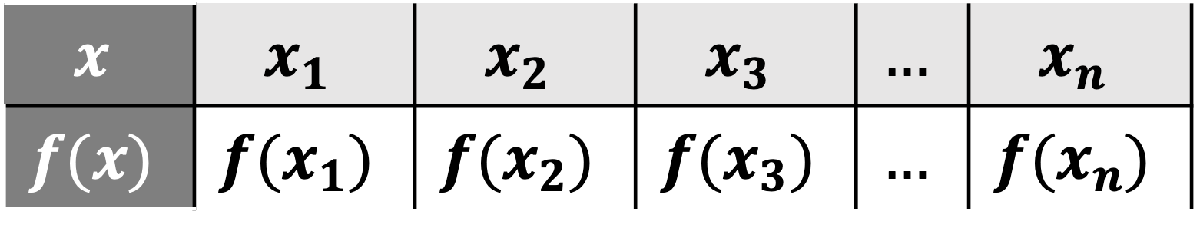

We effectively do the same thing in MATLAB, where $x$ and $f(x)$ are represented as vectors. Let's plot some functions.

Create a vector representing $\{x\,|\,x \in [-5,5]\}$ with 100 elements, call it `x`

X = linspace(-5,5, 100)

X =   -5.0000e+00  -4.8990e+00  -4.7980e+00  -4.6970e+00  -4.5960e+00  -4.4949e+00  -4.3939e+00  -4.2929e+00  -4.1919e+00  -4.0909e+00  -3.9899e+00  -3.8889e+00  -3.7879e+00  -3.6869e+00  -3.5859e+00  -3.4848e+00  -3.3838e+00  -3.2828e+00  -3.1818e+00  -3.0808e+00  -2.9798e+00  -2.8788e+00  -2.7778e+00  -2.6768e+00  -2.5758e+00  -2.4747e+00  -2.3737e+00  -2.2727e+00  -2.1717e+00  -2.0707e+00  -1.9697e+00  -1.8687e+00  -1.7677e+00  -1.6667e+00  -1.5657e+00  -1.4646e+00  -1.3636e+00  -1.2626e+00  -1.1616e+00  -1.0606e+00  -9.5960e-01  -8.5859e-01  -7.5758e-01  -6.5657e-01  -5.5556e-01  -4.5455e-01  -3.5354e-01  -2.5253e-01  -1.5152e-01  -5.0505e-02


Create a vector representing $f(x)=4x+5$, call it `f`.

- First, each element of `x` by 4

- Next, add 5 to each element

f = 4*X + 5

f =   -1.5000e+01  -1.4596e+01  -1.4192e+01  -1.3788e+01  -1.3384e+01  -1.2980e+01  -1.2576e+01  -1.2172e+01  -1.1768e+01  -1.1364e+01  -1.0960e+01  -1.0556e+01  -1.0152e+01  -9.7475e+00  -9.3434e+00  -8.9394e+00  -8.5354e+00  -8.1313e+00  -7.7273e+00  -7.3232e+00  -6.9192e+00  -6.5152e+00  -6.1111e+00  -5.7071e+00  -5.3030e+00  -4.8990e+00  -4.4949e+00  -4.0909e+00  -3.6869e+00  -3.2828e+00  -2.8788e+00  -2.4747e+00  -2.0707e+00  -1.6667e+00  -1.2626e+00  -8.5859e-01  -4.5455e-01  -5.0505e-02   3.5354e-01   7.5758e-01   1.1616e+00   1.5657e+00   1.9697e+00   2.3737e+00   2.7778e+00   3.1818e+00   3.5859e+00   3.9899e+00   4.3939e+00   4.7980e+00


Plot $f(x)$ using the syntax `plot(x,f)`

plot(X, f)

Put a title, xlabel, and ylabel on the figure

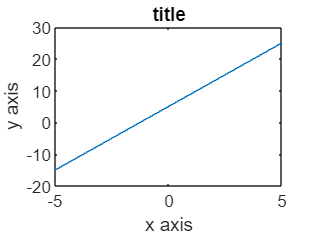

title('title')
xlabel('x axis')
ylabel('y axis')

#### Multiplying Vectors Together

Create a vector representing $g(x)=x^2$, call it `g`.

We want to multiply each element of $\textbf{x}$ by itself: it is helpful in coding to think about $x^2$ as $x*x$. To do this we need to use element-wise operations. This is achieved by using the "dot" notation.

g = X.*X; % (Or X.*^2)

The way to think about this visually is

`x.*x`$= [\matrix{x_1 & x_2 & \dots & x_n}].*[\matrix{x_1 & x_2 & \dots & x_n}]=[\matrix{x_1\, x_1 & x_2\, x_2 & \dots & x_n\, x_n}]$ 

The above can be extended to any two general vectors $\textbf{a}$ and $\textbf{b}$:

`a.*b`$= [\matrix{a_1 & a_2 & \dots & a_n}].*[\matrix{b_1 & b_2 & \dots & b_n}]=[\matrix{a_1\, b_1 & a_2\, b_2 & \dots & a_n\, b_n}]$

You can also raise each element of a vector to the p-th power using, for example,

`a.^p`$= [\matrix{a_1^p & a_2^p & \dots & a_n^p}]$

Create row vectors representing the 3 following functions:


$$h(x) = \sin{(x)}, \quad k(x) = \cos{(x)}, \quad u(x) = h(x)k(x)$$


Plot the functions on a single figure using the `hold on` command.